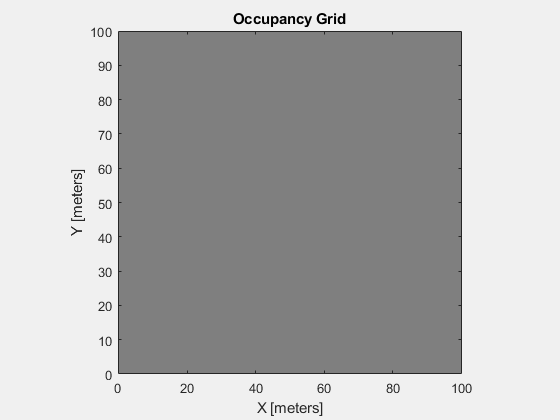

% Create an empty map of the same dimensions as the test track map                      
roverOccupancyGrid = occupancyMap(100,100);  % Make empty map the same size

    
    % Create free floating figure (Rover occupancy grid)
    figureRoverOccupancy = figure('name', 'RoverOccupancyGrid', 'NumberTitle', 'off', 'Visible', 'on');
    figure(figureRoverOccupancy);                            
    show(roverOccupancyGrid);

    distance = [11 13 15 13 11];


    [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, figureRoverOccupancy, 2, [42 -71], distance);

Array indices must be positive integers or logical values.

Error in avoid_loop>findGridPos (line 110)
        obstaclePosX = roverLocation(0) + (distance*cosd(modulo))

Error in avoid_loop>SharpIRRange (line 20)
            [obstaclePosX, obstaclePosY] = findGridPos(angle(i), distance(i), roverLocation);

    function [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, distance)
%      rawRangeData1 = SENSE_ADC(adcDevice1);
%      rawRangeData2 = SENSE_ADC(adcDevice2);
%      rawRangeData = [rawRangeData2(1:3),rawRangeData1(1:2)];
     angles = [-pi/3 -pi/6 0 pi/6 pi/3]; % chagne this later     
     threshold = 40;
    for i=1:5
        if distance < threshold
            [obstaclePosX, obstaclePosY] = findGridPos(angle(i), distance(i), roverLocation);
            updateOccupancy(roverOccupancyGrid, [obstaclePosX obstaclePosY], 0.1)
        end   
    end  
    end

function [gridIndex] = GPSCoordToGridIndex(GPSCoordinate)
    bottom_left_corner = [42.293000, -71.264461];
    xgrid = (GPSCoordinate(1) - bottom_left_corner(1))/(10^(-5)); % plot it on to 100 by 100
    ygrid = (GPSCoordinate(2) - bottom_left_corner(2))/(10^(-5));
    gridIndex = [xgrid ygrid];  
end

function [vAvoid, wAvoid] =  SharpIRAvoid(adcDevice1, adcDevice2)
     rawRangeData1 = SENSE_ADC(adcDevice1);
     rawRangeData2 = SENSE_ADC(adcDevice2);
     rawRangeData = [rawRangeData2(1:3),rawRangeData1(1:2)];
     angles = [-pi/3 -pi/6 0 pi/6 pi/3]; % chagne this later     
     threshold = 40;
     for i = 1:5
        % voltage to distance     
        distance = (rawRangeData(i) - 2.805)/(-0.03316);
     end  
     sensorArray = distance(1:5)   % add virtual middle to left array
%     sensorArray = vertcat(s1, portSensors);           % add right array
     TF = isnan(sensorArray);                          % find any Nan values
     sensorArray(TF) = 12;                             % replace Nan values
      for iScanTransform = 1:5
            if(sensorArray(iScanTransform) < 5)       % if range is shorter than N vote do
                sensorArray(iScanTransform) = -1.5;     % not turn in this sensor direction
            else
                sensorArray(iScanTransform) = 1;      % else can turn this way
            end
      end
    wAvoid = sensorArray';               % flip vertical ranges to horizontal wAvoid
               % flip array to match tp down boat coordinate system
    vAvoid = [0 0 0 0 0];            % set better slow down velocity policy in your student arbiter
end

function [roverOccupancyGrid] =  SharpSONARRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1, adcDevice2)
     rawRangeData1 = SENSE_ADC(adcDevice1);
     rawRangeData2 = SENSE_ADC(adcDevice2);
     rawRangeData = [rawRangeData1(3:4)];
     angles = [-pi/2 pi/2]; % chagne this later     
     threshold = 40;
     for i = 1:2
        % voltage to distance     
        distance = (rawRangeData(i) - 0.01063)/(0.01584);
        if distance < threshold
            [obstaclePosX, obstaclePosY] = findGridPos(angles(i), distance, roverLocation);
            updateOccupancy(roverOccupancyGrid, [obstaclePosX obstaclePosY], 0.1)
        end   
     end  
end

function [vAvoid, wAvoid] =  SharpSONARAvoid(adcDevice1, adcDevice2)
     rawRangeData1 = SENSE_ADC(adcDevice1);
     rawRangeData2 = SENSE_ADC(adcDevice2);
     rawRangeData = [rawRangeData1(3:4)];
     angles = [-pi/2 pi/2]; % chagne this later     
     threshold = 40;
     for i = 1:2
        % voltage to distance     
        distance = (rawRangeData(i) - 0.01063)/(0.01584);
     end  
     sensorArray = distance(1:2)   % add virtual middle to left array
%     sensorArray = vertcat(s1, portSensors);           % add right array
     TF = isnan(sensorArray);                          % find any Nan values
     sensorArray(TF) = 12;                             % replace Nan values
      for iScanTransform = 1:2
            if(sensorArray(iScanTransform) < 15)       % if range is shorter than N vote do
                sensorArray(iScanTransform) = -1.5;     % not turn in this sensor direction
            else
                sensorArray(iScanTransform) = 1;      % else can turn this way
            end
      end
    wAvoid = sensorArray';               % flip vertical ranges to horizontal wAvoid
               % flip array to match tp down boat coordinate system
    vAvoid = [0 0];            % set better slow down velocity policy in your student arbiter
end

function [obstaclePosX, obstaclePosY] = findGridPos(omega, distance, roverLocation) % Helper function for sonar / IR
    if omega < 0
            omega = 360+omega;
    elseif omega > 360
        omega = omega-360;
    end
    quo = omega/90;
    modulo = mod(omega,90);
    if floor(quo) == 0 % Quadrant I
        obstaclePosX = roverLocation(0) + (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) + (distance*sind(modulo))
    elseif floor(quo) == 1 % Quadrant IV
        obstaclePosX = roverLocation(0) + (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) - (distance*sind(modulo))
    elseif floor(quo) == 2 % Quadrant III
        obstaclePosX = roverLocation(0) - (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) - (distance*sind(modulo))
    elseif floor(quo) == 3 % Quadrant IV
        obstaclePosX = roverLocation(0) - (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) + (distance*sind(modulo))
    end
end
